
P1 = [.33, 1.71887, 1.75]

P1 =     0.3300    1.7189    1.7500


P2 = [.15, 50, 6.66]

P2 =     0.1500   50.0000    6.6600


P3 = [.018, 4, 3]

P3 =     0.0180    4.0000    3.0000


Q1 = [.24, 5, 0]

Q1 =     0.2400    5.0000         0


Q2 = [.24, 5, 6.66]

Q2 =     0.2400    5.0000    6.6600



N = cross(P2-P1,P3-P1); % Normal to the plane of the triangle
P0 = Q1 + dot(P1-Q1,N)/dot(Q2-Q1,N)*(Q2-Q1) % The point of intersection

P0 =     0.2400    5.0000    2.3445




amp = [.33, .15, .018]

amp =     0.3300    0.1500    0.0180


initial = [1.71887, 50, 4]

initial =     1.7189   50.0000    4.0000


time = [1.75, 6.66, 3]

time =     1.7500    6.6600    3.0000


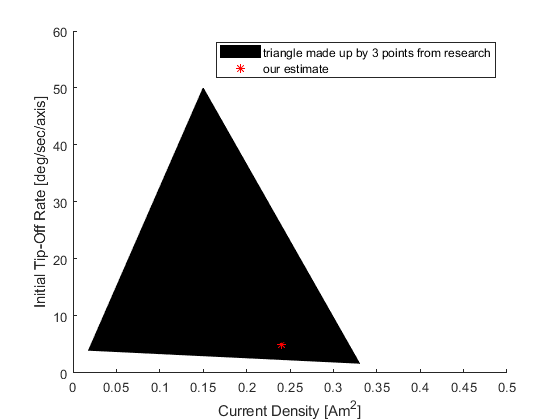


h=patch('Faces',1:3,'Vertices',[P1;P2;P3]);

xlabel("Current Density [Am^2]")
ylabel("Initial Tip-Off Rate [deg/sec/axis]")
zlabel("Time [orbits]")
xlim([0,.5])
ylim([0,60])
zlim([0,10])
hold on
plot3(.24, 5, 2.3445, '*r')
legend("triangle made up by 3 points from research", "our estimate")